# Module 4 Practice 2

## Coin Counting

Count the types and total value of valid coins. 

For this problem, your code will need to do the following: 

- Provide a mask to accurately segment the coins from the background. Use variable name `coinMask`.

- Create the masked image. Use variable name  `maskedCoinImage`. 

- Calculate the area and perimeter of each coin. Provide the results in a table variable `coinSizes`. **Hint: **Remember, to get a table output directly from the `regionprops` function, use the syntax shown in [this documentation example](https://www.mathworks.com/help/images/ref/regionprops.html#buoogbr-1).

- Analyze the mask region properties to determine the *number of each coin type* present. Use variable names `nDimes`, `nNickels`, `nQuarters`, and `nFiftyCents`. **Note:** Although you can see the correct numbers here by looking at the image, and could hard code the answers, in your final project you'll need to determine the coin types again for an image you will not know ahead of time. 

- Calculate the total $ value of coins present. Use variable name `USD`. 

coinImage = imread("coinImage.png");

coinMask = coinImage < 120;
se = strel("disk",5,0);
coinMask = imdilate(coinMask,se);
coinMask = imerode(coinMask,se);
coinMask = imcomplement(coinMask);

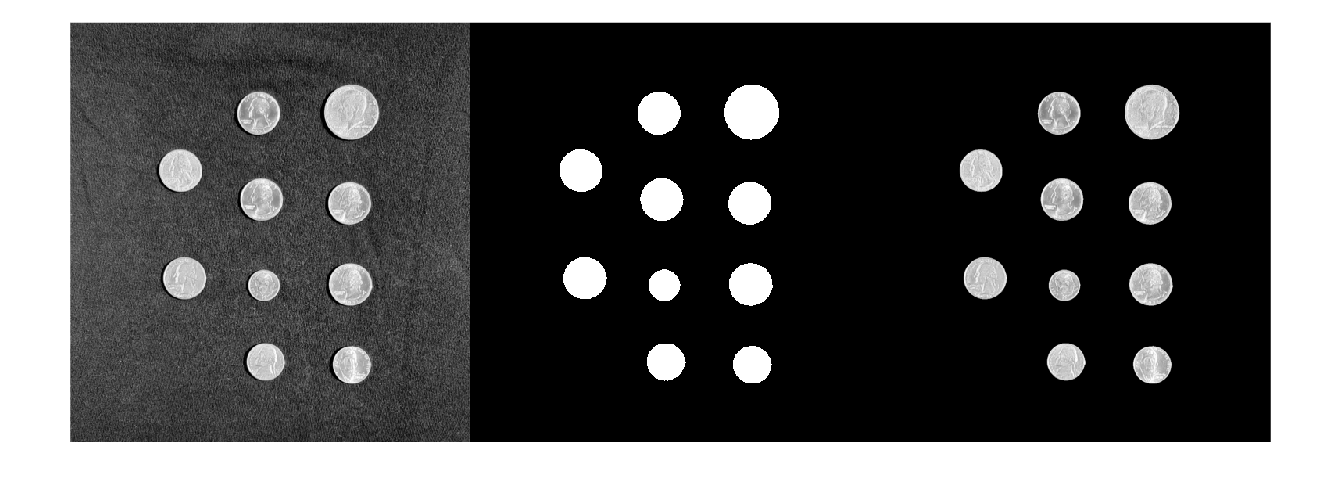

maskedCoinImage = coinImage;
maskedCoinImage(~coinMask) = 0;
montage({coinImage, coinMask, maskedCoinImage}, "size", [1 3])

coinSizes = regionprops("table", coinMask, "Area", "Perimeter")

coinSizes = 10×2 table
    Area     Perimeter
    _____    _________

     7732     309.54  
     7716     308.94  
     7838     311.94  
     7722     309.31  
     6047     274.22  
     4210     227.27  
    12754     401.53  
     7759      311.2  
     7815     311.75  
     6126     275.82  


nDimes = coinSizes.Area < 4500;
nDimes = sum(nDimes);
nNickels = (coinSizes.Area > 4500 & coinSizes.Area <7000);
nNickels = sum(nNickels);
nQuarters = (coinSizes.Area > 7000 & coinSizes.Area < 9000);
nQuarters = sum(nQuarters);
nFiftyCents = coinSizes.Area > 9000;
nFiftyCents = sum(nFiftyCents);

USD = nFiftyCents*0.5 + nQuarters*0.25 + nNickels*0.05 + nDimes*0.1

USD = 2.2000